# Spatial Resolution of Espros DME660

Kevin V. Mack, Clarkson University, Department of Electrical and Computer Engineering

pixel_res = [320, 240];
pixel_area = [20 20]; % micro-meters
photo_area = [6.4, 4.8] % millimeters

photo_area =     6.4000    4.8000


% Using the figure of a 30 x 30 cm target at 2.0 meters standoff distance
d = [1.0, 2.0, 3.0, 4.0, 5.0]; % distances in meters
VFOV = [21.0, 30.0, 45.0, 59.0, 70.0]'; % cm
HFOV = [26.5, 38.5, 57.5, 72.5, 90.0]'; % cm
HFOV./VFOV

ans =     1.2619
    1.2833
    1.2778
    1.2288
    1.2857



for i = 1:size(d,2)
    sp_res_V(i) = VFOV(i)/(pixel_res(2)); % answer in cm
    sp_res_H(i) = HFOV(i)/(pixel_res(1));% answer in cm
end
Spatial_V_cm = sp_res_V';
Spatial_H_cm = sp_res_H';
Spatial_cm_sq = (sp_res_V.*sp_res_H)';
distance_m = d';
table(distance_m, VFOV, HFOV)

ans = 5×3 table
    distance_m    VFOV    HFOV
    __________    ____    ____

        1          21     26.5
        2          30     38.5
        3          45     57.5
        4          59     72.5
        5          70       90


table(distance_m, Spatial_V_cm, Spatial_H_cm, Spatial_cm_sq)

ans = 5×4 table
    distance_m    Spatial_V_cm    Spatial_H_cm    Spatial_cm_sq
    __________    ____________    ____________    _____________

        1            0.0875         0.082812        0.0072461  
        2             0.125          0.12031         0.015039  
        3            0.1875          0.17969         0.033691  
        4           0.24583          0.22656         0.055697  
        5           0.29167          0.28125         0.082031  


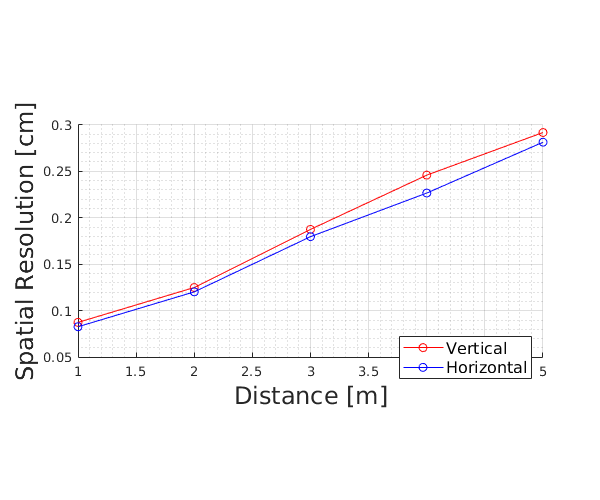

figure
hold on
grid on
grid minor
plot(distance_m, Spatial_V_cm, 'r-o')
plot(distance_m, Spatial_H_cm, 'b-o')
xlabel('Distance [m]', 'FontSize', 18)
ylabel('Spatial Resolution [cm]', 'FontSize', 18)
legend('Vertical', 'Horizontal', 'location', 'best', 'FontSize',12)
% axis([0 5 0 1.6])
pbaspect([2.0 1 1])

figure
hold on
grid on

## Extending to ten pixels per feature

Spatial_V_10p_cm = sp_res_V'*2.5;
Spatial_H_10p_cm = sp_res_H'*2.5;
distance_m = d';
table(distance_m, Spatial_V_10p_cm, Spatial_H_10p_cm)

ans = 5×3 table
    distance_m    Spatial_V_10p_cm    Spatial_H_10p_cm
    __________    ________________    ________________

        1             0.21875             0.20703     
        2              0.3125             0.30078     
        3             0.46875             0.44922     
        4             0.61458             0.56641     
        5             0.72917             0.70312     
